## Очищення середовища

clear, close all

## Завантаження та відображення вхідного зображення з бібліотеки

pout = imread('pout.tif')

pout = 291×240 uint8 matrix
   107   108   107   106    99   101   102   107   107   103   112   164   200   197   170   182   213   214   212   197   137   112   110   109   112   110   107   105   106   106   107   109   108   106   106   106    99    98    99   101    99   102   103   105   103   119   147   205   204   209
   109   106   108   107   103   102   103   110   113   108   128   182   210   210   182   166   189   210   213   210   167   119   110   108   112   110   106   106   107   107   105   107   106   107   108   107   106   102    95   103   106   108   121   120   109   128   161   208   207   212
   107   106   110   110   106   107   107   120   133   133   125   151   181   189   175   151   159   204   210   212   189   137   119   107   110   110   107   108   108   107   106   106   106   105   106   108   107   105    98   103   128   150   164   137   121   133   169   208   210   215
   106   107   108   108   108   108   108   114   126   146   133   

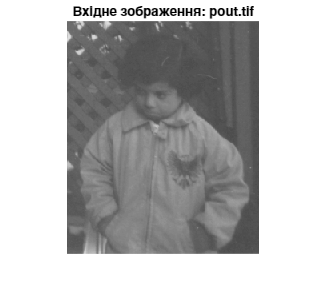

imshow(pout)
title('Вхідне зображення: pout.tif');

## Завантаження та відображення вхідного зображення з ПК

thor = imread('D:\Universety\Applied intelligent signal and image processing\Lab1\Thor.jpg')

thor = 277×182×3 uint8 array
thor(:,:,1) =

     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     3     3     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

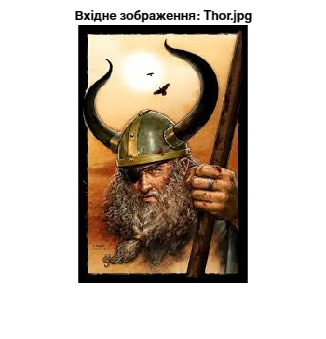

figure,imshow(thor)
title('Вхідне зображення: Thor.jpg');

## Перевірка розмірів та характеристик зображення

size(thor)

ans =    277   182     3


whos thor

  Name        Size                Bytes  Class    Attributes

  thor      277x182x3            151242  uint8              



## Відображення зображення та його гістограми

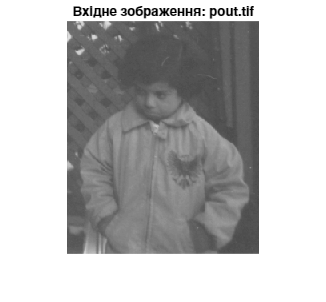

imshow(pout)
title('Вхідне зображення: pout.tif');

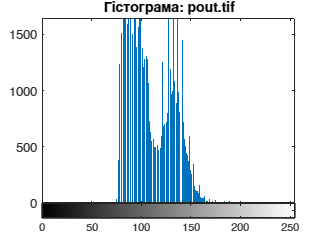

figure,imhist(pout)
title('Гістограма: pout.tif');

## Збереження зображення у файл

imwrite(pout,'save_pout.tif')

## Інвертуєм значення яскравостей на

## зображенні

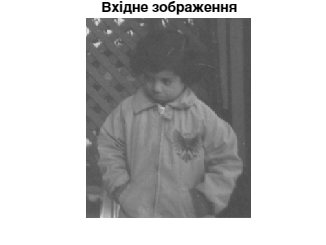

pout_imadjust = imadjust(pout,[0,1],[1,0],1.5);
imshow(pout);
title('Вхідне зображення');

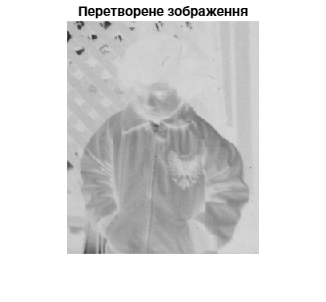

figure, imshow(pout_imadjust);
title('Перетворене зображення');

## Що таке "гістограма розподілу яскравостей"?

Гістограма розподілу яскравостей — це графічне представлення кількості пікселів для кожного значення яскравості на зображенні.

Вона показує, як часто зустрічаються певні значення яскравості (від 0 до 255) у зображенні. Гістограма дозволяє оцінити контрастність і освітленість зображення.

Приклад:

Використовуючи команду **imhist**, можна побудувати гістограму для зображення.

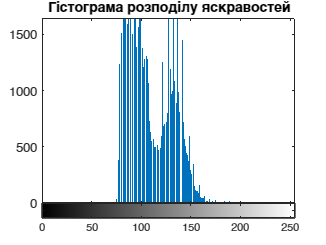

figure, imhist(pout)
title('Гістограма розподілу яскравостей');

# Контрольні питання

## Що таке "контрастність зображення"?

Контрастність зображення — це різниця між найсвітлішими і найтемнішими пікселями на зображенні. 

Висока контрастність означає, що зображення має велику різницю між світлими та темними ділянками. Низька контрастність призводить до "плоских" зображень з менш вираженими деталями.

Контрастність можна коригувати за допомогою різних методів, таких як лінійне розтягування яскравості або гамма-корекція.

## Як при контрастуванні змінюється гістограма розподілу яскравостей зображення?

При контрастуванні зображення гістограма розподілу яскравостей зазвичай

змінюється таким чином, що більше пікселів зосереджено на кінцях шкали

яскравості (ближче до 0 і 255), що збільшує контраст між темними і світлими

ділянками зображення.

При зменшенні контрастності гістограма стиснеться в центрі шкали.

Приклад:

Для корекції контрастності можна використати команду **imadjust**.

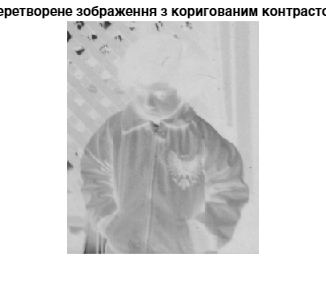

pout_imadjust = imadjust(pout, [0, 1], [1, 0], 1.5);
figure, imshow(pout_imadjust)
title('Перетворене зображення з коригованим контрастом');

## Як за необхідності зменшити контрастність зображення?

Для зменшення контрастності зображення можна використовувати команду

**imadjust** з параметрами, які зменшують різницю між темними і світлими пікселями.

Це можна зробити, зменшивши значення діапазону яскравості або застосувавши гамма-корекцію.

Наприклад, для зменшення контрастності:

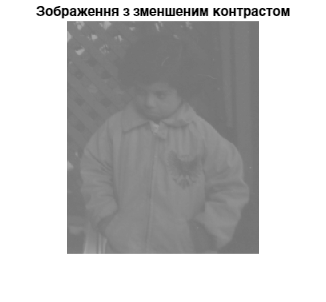

pout_imadjust_low_contrast = imadjust(pout, [0, 1], [0.3, 0.7], 0.8);
figure, imshow(pout_imadjust_low_contrast);
title('Зображення з зменшеним контрастом');

## Як одержати негативне зображення?

Негативне зображення — це зображення, де кожен піксель має протилежне

значення яскравості, тобто:

- Яскравість пікселів зображення, що мали низьке значення, стає високою.

- Яскравість пікселів з високим значенням стає низькою.

Для цього можна застосувати операцію:

**new_value = 255 - old_value**

Наприклад:

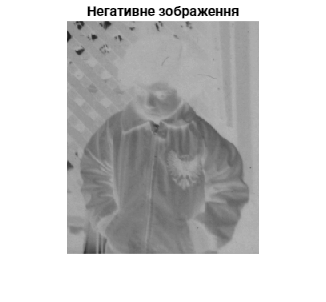

pout_negative = imcomplement(pout);
figure, imshow(pout_negative);
title('Негативне зображення');